# 3.2. Движение заряженных частиц

#### Сила Лоренца

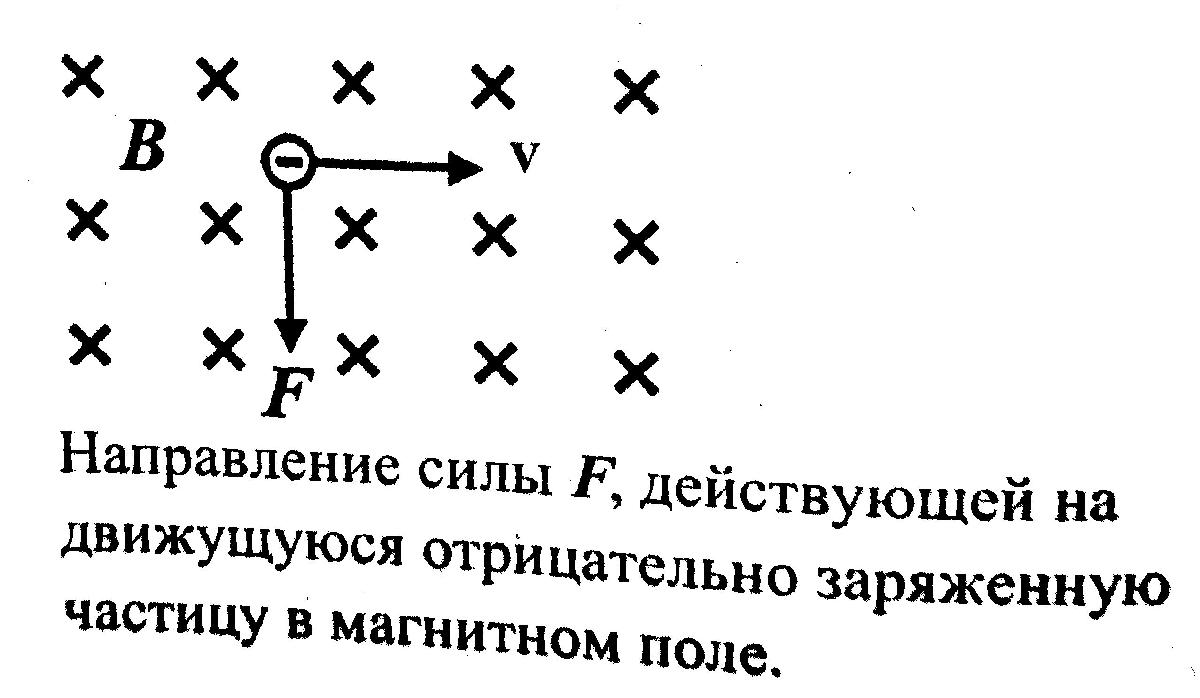


$$\mathit{\mathbf{F}}=Q\left(\mathit{\mathbf{E}}+\mathit{\mathbf{v}}\times \mathit{\mathbf{B}}\right)$$


clear
syms rot(x) grad(x) div(x) sprod(x,y) vprod(x,y)
syms F Q E v B
% F=Q*(E+v×B)
F==Q*(E+vprod(v,B))

$$ans = F=Q\,\left(\text{E}+\mathrm{vprod}\left(v,B\right)\right)$$

% vprod(v,B) = v×B

#### Сила тока

syms Q t I d(f,x,n)
I==d(Q,t,1)

$$ans = \text{I}=d\left(Q,t,1\right)$$

#### Плотность тока

syms j n Q v avrg(v)
j==n*Q*avrg(v)

$$ans = j=Q\,n\,\mathrm{avrg}\left(v\right)$$

% n = число зарядов Q в единице побъема
% avrg(v) = <v> = скорость дрейфа носителей заряда

#### Полная энергия одной частицы, движущейся в электрическом поле (нерелятивистский случай)

syms W_poln m v Q t V
W_poln==1/2*m*v^2+Q*V

$$ans = W_{\mathrm{poln}}=\frac{m\,v^{2}}{2}+Q\,V$$

% m = масса частицы

#### Скорость дрейфа заряженной частицы под действием магнитного поля и немагнитной силы 

% B = плотность магнитного потока, B_v - вектор
% F = немагнитная сила, F_v - вектор
% q = заряд частицв
% m = масса частицы
% u = скорость дрейфа, u_v - вектор
% v = скорость частицы, v_o - ортогональная составляющая, v_p - параллельная составляющая
% u_o = u_|_ = составляющая, перпендикулярная магнитному полю
% u_p = u||  = составляющая, параллельная магнитному полю
% gradB = grad(B)


$${\mathit{\mathbf{u}}}_{\perp } =-\frac{1}{q\;B^2 }\mathit{\mathbf{B}}\times \left(\mathit{\mathbf{F}}-\frac{1}{B}\frac{m\;v_{\perp }^2 }{2}\;\mathrm{grad}\;B-m\;\frac{d}{\textrm{d}t}\mathit{\mathbf{u}}\right)$$


syms u_o q B F m v_o v_p B B_v gradB u t E_v
u_o==-1/(q*B^2)*vprod(B,(F-1/B*m*v_o^2/2*grad(B) - m*d(u,t,1)))

$$ans = u_{o}=-\frac{\mathrm{vprod}\left(B,F-m\,d\left(u,t,1\right)-\frac{m\,{v_{o}}^{2}\,\mathrm{grad}\left(B\right)}{2\,B}\right)}{B^{2}\,q}$$

Для u||: $\mathit{\mathbf{B}}\cdot \left(F-\frac{1}{B}\frac{m\;v_{\perp }^2 }{2}\;\mathrm{grad}\;B-m\;\frac{d}{\textrm{d}t}\mathit{\mathbf{u}}\right)=0$

sprod(B,(F-1/B*m*v_o^2/2*grad(B)-m*d(u,t,1)))==0

$$ans = \mathrm{sprod}\left(B,F-m\,d\left(u,t,1\right)-\frac{m\,{v_{o}}^{2}\,\mathrm{grad}\left(B\right)}{2\,B}\right)=0$$

*Особые случаи*

- 
$$\mathit{\mathbf{F}}=q\;\mathit{\mathbf{E}};\mathrm{grad}\;B=0;\frac{d}{\textrm{d}t}u=0$$


F==q*E, grad(B)==0, d(u,t,1)==0

$$ans = F=\text{E}\,q$$

$$ans = \mathrm{grad}\left(B\right)=0$$

$$ans = d\left(u,t,1\right)=0$$


$${\mathit{\mathbf{u}}}_{\bot } =-\frac{1}{B^2 }\mathit{\mathbf{B}}\times \mathit{\mathbf{E}}$$


syms B E
u_o==-1/B^2*vprod(B,E)  % (независимо от q,v)

$$ans = u_{o}=-\frac{\mathrm{vprod}\left(B,\text{E}\right)}{B^{2}}$$

% vprod(B,E)=B×E


2. $F=\frac{\textrm{d}}{\textrm{d}t}u=0$

F==d(u,t,1)==0

$$ans = \left(F=d\left(u,t,1\right)\right)=0$$


$$u_{\perp } =\frac{m\;v_{\perp }^2 }{2\;q\;B^3 }\mathit{\mathbf{B}}\times \mathrm{grad}\;B$$


u_o==m*v_o^2/(2*q*B^3)*vprod(B,grad(B))

$$ans = u_{o}=\frac{m\,{v_{o}}^{2}\,\mathrm{vprod}\left(B,\mathrm{grad}\left(B\right)\right)}{2\,B^{3}\,q}$$

3. du/dt меньше центробежного ускорения


$$u_{\perp } =-\frac{1}{q\;B^2 }B\times \left\lbrack F-\frac{m}{B}\left(\frac{v_{\perp }^2 }{2}+v_{\|}^2 \right)\mathrm{grad}\;B\right\rbrack$$


u_o==-1/(q*B^2)*vprod(B,(F-m/B*(v_o^2/2+v_p^2)*grad(B)))

$$ans = u_{o}=-\frac{\mathrm{vprod}\left(B,F-\frac{m\,\mathrm{grad}\left(B\right)\,\left(\frac{{v_{o}}^{2}}{2}+{v_{p}}^{2}\right)}{B}\right)}{B^{2}\,q}$$

#### Обобщенный импульс


$$\mathit{\mathbf{p}}=m\;\mathit{\mathbf{v}}+Q\;\mathit{\mathbf{A}}$$


syms p m v Q A
p==m*v+Q*A

$$ans = p=m\,v+A\,Q$$

#### Обобщенный потенциал силы Лоренца


$$V_{\mathrm{gen}} =Q\;\left(V-v\cdot A\right)$$


syms V_gen Q V v A
V_gen==Q*(V-sprod(v,A))

$$ans = V_{\mathrm{gen}}=Q\,\left(V-\mathrm{sprod}\left(v,A\right)\right)$$

#### Излучение в точке P от заряда, движущегося с ускорением (v<<c0)

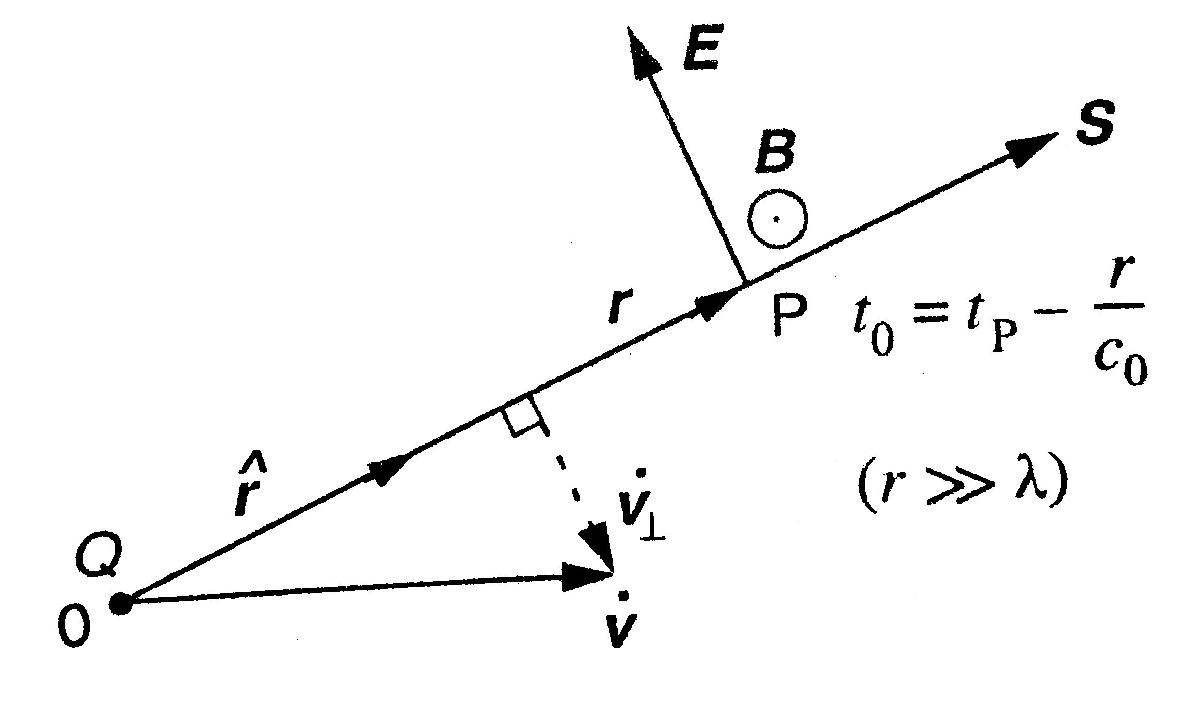


$$E\left(r,t_p \right)=-\frac{Q}{4\pi \varepsilon_0 c_0^2 r}{\dot{v} }_{\perp } \left(t_0 \right)$$


syms E(r,t_P) Q epsilon0 c0 r v_o t0
E(r,t_P)==-Q/(4*pi*epsilon0*c0^2*r)*d(v_o,t0,1)

$$ans = \text{E}\left(r,t_{P}\right)=-\frac{Q\,d\left(v_{o},t_{0},1\right)}{4\,{c_{0}}^{2}\,\epsilon_{0}\,r\,\pi }$$


$$B=\frac{1}{c_0 }\left(\hat{\mathit{\mathbf{r}}} \times \mathit{\mathbf{E}}\right)$$


syms E r E
B==1/c0*vprod(r,E)

$$ans = B=\frac{\mathrm{vprod}\left(r,\text{E}\right)}{c_{0}}$$

% vprod(r,E) = r×E

Вектор Пойтинга


$$\mathit{\mathbf{S}}=\frac{1}{\mu_0 }\mathit{\mathbf{E}}\times \mathit{\mathbf{B}}$$


syms S mu0 E B
S==1/mu0*vprod(E,B)

$$ans = S=\frac{\mathrm{vprod}\left(\text{E},B\right)}{\mu_{0}}$$

% vprod(E,B) = E×B